# Ariadna Cortés Danés - Exercici 3 (Parcial 2)

clear all, close all, format long,

Escollir el mètode més eficient per calcular el valor de:


$$$IA=\int^4_{-4}\left(x^2+ \frac{1}{4}\right)^A\cdot e^{-x^2}dx.$$$


Per A=2/3, es demana

**(Q1)**  Representeu gràficament la funció $$f_A(x) = \left(x^2+ \frac{1}{4}\right)^A\cdot e^{-x^2}$$sobre el recinte d'integració [a,b]=[−4,4].

fa = @(x) exp(-x.^2).*(x.^2 + 0.25).^(2/3)

fa = function_handle with value:
    @(x)exp(-x.^2).*(x.^2+0.25).^(2/3)


x = linspace(-4,4,100)

x =   -4.000000000000000  -3.919191919191919  -3.838383838383838  -3.757575757575758  -3.676767676767677  -3.595959595959596  -3.515151515151515  -3.434343434343434  -3.353535353535353  -3.272727272727273  -3.191919191919192  -3.111111111111111  -3.030303030303030  -2.949494949494949  -2.868686868686869  -2.787878787878788  -2.707070707070707  -2.626262626262626  -2.545454545454545  -2.464646464646465  -2.383838383838384  -2.303030303030303  -2.222222222222222  -2.141414141414141  -2.060606060606061  -1.979797979797980  -1.898989898989899  -1.818181818181818  -1.737373737373737  -1.656565656565657  -1.575757575757576  -1.494949494949495  -1.414141414141414  -1.333333333333333  -1.252525252525253  -1.171717171717172  -1.090909090909091  -1.010101010101010  -0.929292929292929  -0.848484848484849  -0.767676767676768  -0.686868686868687  -0.606060606060606  -0.525252525252525  -0.444444444444444  -0.363636363636364  -0.282828282828283  -0.202020202020202  -0.121212121212121  -0.04040404040

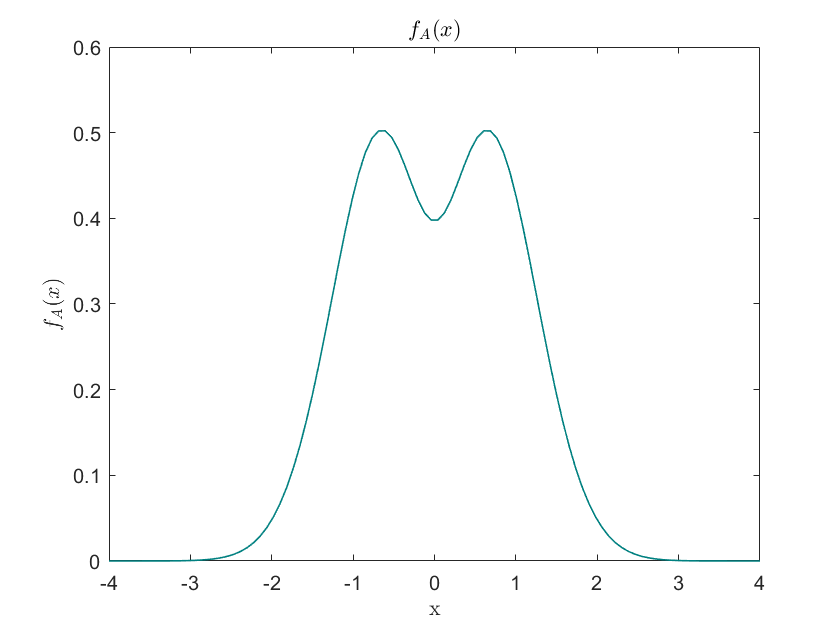

plot(x,fa(x),'Color',[0 0.5 0.5],'LineWidth',0.8)
title('$f_A(x)$','Interpreter',"latex")
xlabel('x','Interpreter',"latex")
ylabel('$f_A(x)$','Interpreter',"latex")

- **Resposta:** Gràfica.

**(Q2) ** Useu la regla del punt mig per a determinar $$I_A$$�  prenent� n=8, 64, 512 subintervals.

a = 4; b= -4; 

n = 8;
i8 = midp(fa,a,b,n)

i8 =   -1.383020305182107



n = 64;
i64 = midp(fa,a,b,n)

i64 =   -1.365566010179064



n = 512;
i512 = midp(fa,a,b,n)

i512 =   -1.365566003249423


- **Resposta:** Tres valors aproximats de $$I_A$$

**(Q3)** Useu una tècnica de simulació (mètode de Montecarlo) per a determinar $$I_A$$. Preneu 10 mostres de mida $$10^6$$ , obteniu el valor mig de les 10 simulacions com a valor aproximat de  $$I_A$$

valors_i = []


valors_i =

     []



m = 10^6

m =      1000000


for ii = 1:10
    i = montecarlo(fa, m, a, b);
    valors_i = [valors_i i];
end

i_montecarlo = mean(valors_i)

i_montecarlo =   -1.366002497008029


- **Resposta: **Valor mig aproximat de $$I_A$$.

**(Q4) **Useu *integral *de Matlab® per obtenir el valor de $$I_A$$  amb 15 xifres decimals correctes com a mínim. Calculeu l'error absolut i l'error relatiu de les aproximacions dels apartats (Q2) i (Q3). Presenteu els vostres resultats en taules.   

i_real = integral(fa,a,b);

[ea8,er8,dc8,xs8] = errores(i_real,i8);
[ea64,er64,dc64,xs64] = errores(i_real,i64);
[ea512,er512,dc512,xs512] = errores(i_real,i512);
[ea,er,dc,xs] = errores(i_real,i_montecarlo);

taula = [ea8,er8,dc8,xs8; ea64,er64,dc64,xs64; ea512,er512,dc512,xs512; ea,er,dc,xs]';
T = array2table(taula,"VariableNames",{'Trap 8','Trap 64','Trap 512','Montecarlo'});
disp(T)

          Trap 8                Trap 64                 Trap 512               Montecarlo     
    __________________    ____________________    ____________________    ____________________

    0.0174543020453144    7.04227187675599e-09    1.12631015625198e-10    0.000436493871236898
    0.0127817344641129    5.15703514921977e-09    8.24793641365389e-11    0.000319643188417289
                     1                       7                       9                       3
                     1                       7                       9                       3




% el metode mes eficient es trapezis per n = 512

- **Resposta: **Raona i argumenta, quantes xifres significatives correctes s’ han obtingut? Quin mètode és més eficient? 

function r = midp(f,a,b,n)
h = (b - a) / n;
x = a + h * 0.5;
r = 0;
for i=1:n
    r = r + f(x);
    x = x + h;
end
r = r * h;
end

function integral = montecarlo(f, m, a, b)
% Calcula l'integral d'una funcio pel metode de montecarlo del valor
% esperat
% f -referencia a la funcio a la que fer l'integral
% m- nombre de llançaments aleatoris
% a- limit inferior
% b- limit superior
% error: de l'ordre de (1/sqrt(m)
r = rand(1,m)*(b-a) + a;
integral = (b-a)*sum(f(r))/m;
end

function [ea,er,dc,xs] = errores(x,y)
% output -- error absolut, error relatiu, decimals correctes, xifres
% significatives
% input
%   x valor exacte
%   y valor aproximat
ea = abs(x-y);
er = ea./abs(x);
erp = er*100;
dc = fix(-log10(2*ea));
xs = fix(-log10(2*er));
end